## PART 1: KINEMATICS

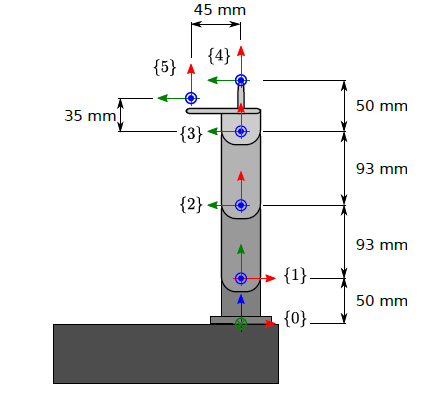

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms t1 t2 t3 t4 

% {0} -> {1}
T01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) L01;
       0 0 0 1];
% {1} -> {2}
T12 = [cos(t2) -sin(t2) 0 L12;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];
% {2} -> {3}
T23 = [1 0 0 L23;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {4}
T34 = [1 0 0 L34;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {5}
T35 = [1 0 0 L35;
       0 1 0 L45;
       0 0 1 0;
       0 0 0 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 143\,\cos\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 143\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 143\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 128\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 45\,\cos\left(t_{1}\right)\,\cos\left(t_{2}\right)+128\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 45\,\cos\left(t_{2}\right)\,\sin\left(t_{1}\right)+128\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

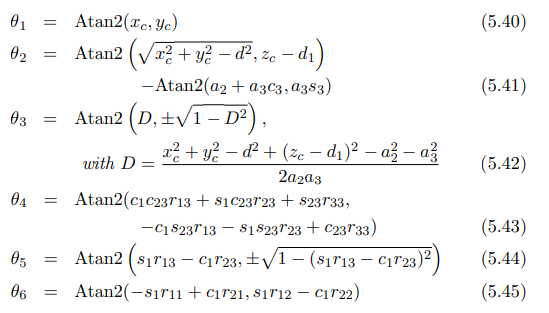

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



t1 = atan2(xc,yc);

t3 = atan2(D, sqrt(1-D^2));

t2 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(t3), L23*sin(t3));

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





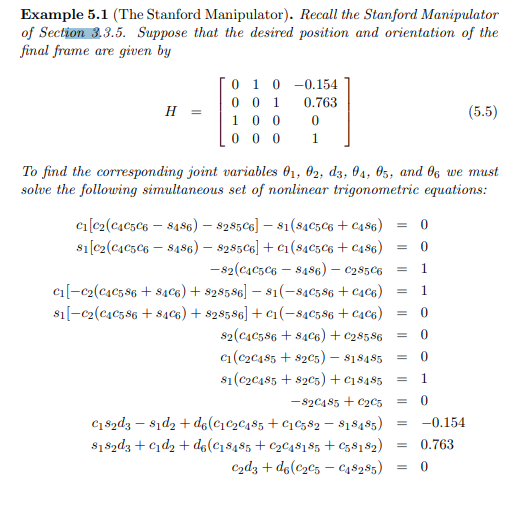

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

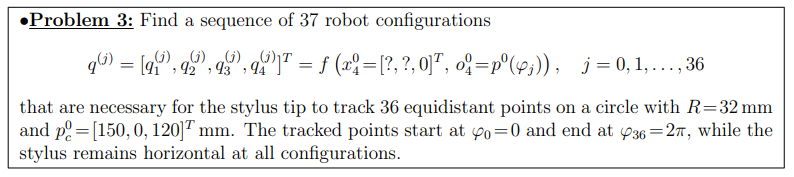


% origin of the circle to be traced
xc = 150;
yc = 100;
zc = 100;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line

angles =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708    1.7453    1.9199    2.0944    2.2689    2.4435    2.6180    2.7925    2.9671    3.1416    3.3161    3.4907    3.6652    3.8397    4.0143    4.1888    4.3633    4.5379    4.7124    4.8869    5.0615    5.2360    5.4105    5.5851    5.7596    5.9341    6.1087    6.2832




dy = cos(angles)*16;
dz = sin(angles)*16;

x = zeros(1,length(angles))

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = yc + dy

y =   116.0000  115.7569  115.0351  113.8564  112.2567  110.2846  108.0000  105.4723  102.7784  100.0000   97.2216   94.5277   92.0000   89.7154   87.7433   86.1436   84.9649   84.2431   84.0000   84.2431   84.9649   86.1436   87.7433   89.7154   92.0000   94.5277   97.2216  100.0000  102.7784  105.4723  108.0000  110.2846  112.2567  113.8564  115.0351  115.7569  116.0000


z = zc + dz

z =   100.0000  102.7784  105.4723  108.0000  110.2846  112.2567  113.8564  115.0351  115.7569  116.0000  115.7569  115.0351  113.8564  112.2567  110.2846  108.0000  105.4723  102.7784  100.0000   97.2216   94.5277   92.0000   89.7154   87.7433   86.1436   84.9649   84.2431   84.0000   84.2431   84.9649   86.1436   87.7433   89.7154   92.0000   94.5277   97.2216  100.0000



[t1,t2,t3] = theta(x,y,z)

t1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


t2 =    -0.7535   -0.7679   -0.7870   -0.8107   -0.8383   -0.8695   -0.9038   -0.9405   -0.9789   -1.0184   -1.0580   -1.0970   -1.1342   -1.1688   -1.1995   -1.2252   -1.2447   -1.2569   -1.2603   -1.2533   -1.2338   -1.2001   -1.1538   -1.0994   -1.0421   -0.9860   -0.9338   -0.8870   -0.8464   -0.8124   -0.7852   -0.7646   -0.7504   -0.7425   -0.7405   -0.7443   -0.7535


t3 =    -0.6158   -0.5996   -0.5909   -0.5897   -0.5961   -0.6099   -0.6310   -0.6591   -0.6937   -0.7343   -0.7805   -0.8315   -0.8867   -0.9452   -1.0062   -1.0686   -1.1308   -1.1909   -1.2455   -1.2899   -1.3173   -1.3213   -1.3007   -1.2608   -1.2088   -1.1500   -1.0882   -1.0257   -0.9641   -0.9047   -0.8483   -0.7959   -0.7482   -0.7058   -0.6692   -0.6391   -0.6158



t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

t4 =     4.5109    4.5091    4.5195    4.5420    4.5760    4.6211    4.6764    4.7411    4.8142    4.8943    4.9801    5.0700    5.1625    5.2556    5.3473    5.4354    5.5172    5.5894    5.6475    5.6849    5.6927    5.6630    5.5961    5.5018    5.3925    5.2776    5.1636    5.0542    4.9521    4.8587    4.7751    4.7021    4.6402    4.5898    4.5514    4.5250    4.5109



% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));



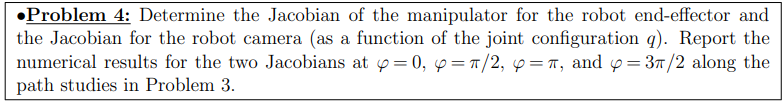

% if you need help figuring out the angles contact Palli
clc
disp("helloo")

helloo


%phi = [0 pi/2 pi 3*pi/2];
phi = pi;
dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

[t1,t2,t3] = theta(x,y,z);
t4 = ones(1,length(x)).*(pi-t1-t2-t3);

for i = 1:1%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34)
end

T04 =     0.3055    0.9522         0  136.6872
   -0.9522    0.3055         0 -136.1632
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.3055    0.9522         0  121.4119
   -0.9522    0.3055         0  -88.5537
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.3055    0.9522         0   93.0000
   -0.9522    0.3055         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 =      1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 =      0     0     1


o1 =      0     0    50


z2 =      0     0     1


o2 =     93     0    50


z3 =      0     0     1


o3 =   121.4119  -88.5537   50.0000


o4 =   136.6872 -136.1632   50.0000


J0 =      0
     0
     1
     0
     0
     0


J1 =   136.1632
  136.6872
         0
         0
         0
    1.0000


J2 =   136.1632
   43.6872
         0
         0
         0
    1.0000


J3 =    47.6095
   15.2752
         0
         0
         0
    1.0000


J =          0  136.1632  136.1632   47.6095
         0  136.6872   43.6872   15.2752
    1.0000         0         0         0
         0         0         0         0
         0         0         0         0
         0    1.0000    1.0000    1.0000